# Copyright of this code belongs to Dipankar Maity (dmaity@uncc.edu).

Do not distribute this code.

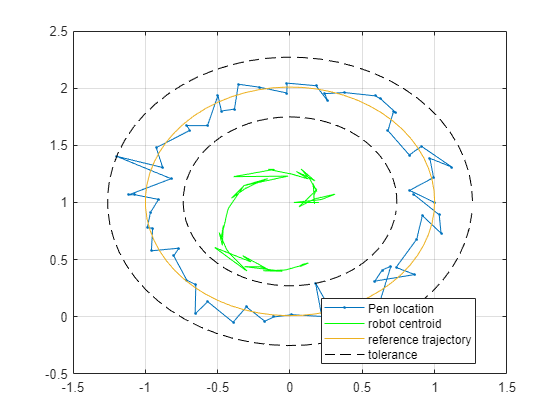

clear all 
% 'D' is the distance of the pen from the base of the robot
% 'k' is the control parameter
global D h k;

down_sample_amount = 5;


velocity_saturation = false;
v_max = 3;
w_max = 8;

% Circle
D = .8; k = 50; h = 0.02;
position = importdata("circle.mat");


l = 1;
for i = 1:down_sample_amount:length(position)
    new_position(:,l) = position(:,i);
    l = l+1;
end
position = new_position;
     
      
state(:,1) =[position(1,1)-D; position(2,1); 0];
xb(1) = state(1,1) + D*cos(state(3,1));
yb(1) = state(2,1) + D*sin(state(3,1));
theta(1) = state(3,1); 
  
  T = size(position,2)-1;
  t = 1:T;
  xVelocity = (position(1,t+1) - position(1,t))/h;
  yVelocity = (position(2,t+1) - position(2,t))/h;

  
for t =1 : T
    n1 = 5*randn(1);
    n2 = 5*randn(1);
    % x= current state
    x= [xb(t); yb(t); theta(t)];
    
    % controller returns the desired velocities
    [v, w] = controller(x, xVelocity(t), yVelocity(t),position(:,t));
    v = v+n1;
    w = w+n2;
    
    if velocity_saturation == 1
        if v > v_max
            v = v_max;
        elseif v < -v_max
            v = -v_max;
        end
    end
        
    if velocity_saturation == 1   
        if w > w_max
            w = w_max;
        elseif w < -w_max
            w = -w_max;
        end
    end
    
    % use the dynamics with desired velocities to generate the velocities
    dot_x = dynamics(x,v,w);
    
     linear_vel(t) = v;
     angular_vel(t) = w;
     
    % integrate the position to get the new position
    xb(t+1) = xb(t) + dot_x(1)*h;
    yb(t+1) = yb(t) + dot_x(2)*h;
    theta(t+1) = theta(t) + dot_x(3)*h;
    
    % centroid dynamics
    state(:,t+1) = state(:,t) + h* [(v)*cos(state(3,t)); (v)*sin(state(3,t)); w];
    
end
% save("noise_centroid.mat","state")

error = [position(1,:) - xb; position(2,:) - yb];
for i = 1:length(error)
    norm_error(i) = norm(error(i));
end

figure
plot(xb, yb, '.-')
hold on;
plot(state(1,:), state(2,:), 'g'); 
plot(position(1,:),position(2,:));
plot_tolerance(position,max(norm_error));
grid on;
legend('Pen location', 'robot centroid', 'reference trajectory','tolerance', "location", 'best')
hold off

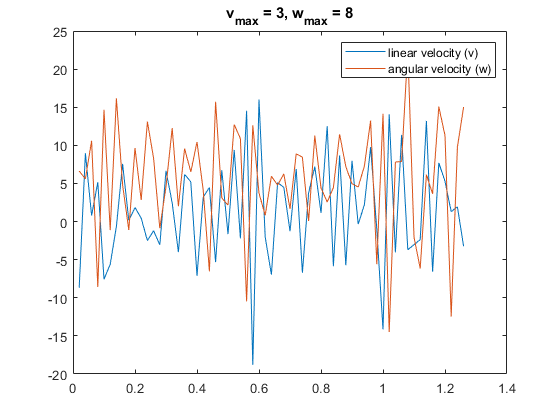


figure
plot([1:size(linear_vel,2)]*h, linear_vel); hold on
plot([1:size(angular_vel,2)]*h, angular_vel);
legend('linear velocity (v)', 'angular velocity (w)')
title("v_{max} = " + v_max + ", w_{max} = " + w_max)

function [v, w] = controller(x, xVelocity, yVelocity,position)
global D k
 

J = [cos(x(3)) -D*sin(x(3));
    sin(x(3))  D*cos(x(3)) ];

v_feedback = [xVelocity; yVelocity] - k*( x(1:2,1)- [position(1); position(2)]);

desired_control = (J)\v_feedback;

v = desired_control(1);
w = desired_control(2);

end

function dot_x = dynamics(x,v,w)
global D

M = [cos(x(3)) -D*sin(x(3));
     sin(x(3))  D*cos(x(3));
     0          1          ];

dot_x = M*[v; w];

end

function [tolerance1, tolerance2] = plot_tolerance(z,d) % function to plot tolerance
% initialize distances between edges of the tolerance line
s = [d; -d];   
for i = [1:length(z)-1]
  theta = atan2(z(2,i+1)-z(2,i),(z(1,i+1)-z(1,i)));
% calcualte 1x2 array with edge points
    x(:,i) = s*sin(theta) + z(1,i);
    y(:,i) = -s*cos(theta) + z(2,i);
  
    
end
tolerance1(1,:) = x(1,:);
tolerance1(2,:) = y(1,:);
tolerance2(1,:) = x(2,:);
tolerance2(2,:) = y(2,:);
plot(x(1,:),y(1,:),'--','color','k')
plot(x(2,:),y(2,:),'--','color','k')
end